clear; close all; rng(1); mpt_init;

MPT searches for solvers on the path ...
 
 LINPROG ............................................ linprog.m 
 QUADPROG .......................................... quadprog.m 
 GLPK .................................................. glpkcc 
 CDD ................................................... cddmex 
 MOSEK ............................................... mosekopt 
 LCP ...................................................... lcp 
 SEDUMI .............................................. sedumi.m 
 PLCP .............................................. mpt_plcp.m 
 MPQP .............................................. mpt_mpqp.m 
 MPLP .............................................. mpt_mplp.m 
 ENUMPLCP ..................................... mpt_enum_plcp.m 
 ENUMPQP ....................................... mpt_enum_pqp.m 
 RLENUMPQP ..................................... mpt_enum_pqp.m 

MOSEK Version 11.0.14 (Build date: 2025-4-3 22:32:03)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform:

yalmip('clear');
optm = which('optimizer');
extrasDir = fileparts(fileparts(optm));
addpath(extrasDir,'-begin');
rehash toolboxcache;

# ACC dynamics

For the controlled vehicle, we use the **Vehicle Body 3DOF** model from Simulink’s Vehicle Dynamics Toolbox. For the leading vehicle, we use a simple velocity-displacement point mass model. Finally, the states and inputs they form are:


$$x = \left[\begin{array}{c}
    x_l - x_c \\
    v_c
\end{array}\right],\quad u = f_c,\quad z = v_l.
$$


where $\( x \)$ represents the distance between the two vehicles$ \( x_l - x_c \)$ and $\( v_c \)$ is the velocity of the controlled vehicle, $\( u \)$ is the controlled vehicle's traction force $\( f_c \)$, and the uncontrolled input $\( z \)$ is the leading vehicle's velocity $\( v_l \)$.

[nx,nz,nu]=deal(2,1,1);

Similarly, we formulate the parameter table for ACC simulation:

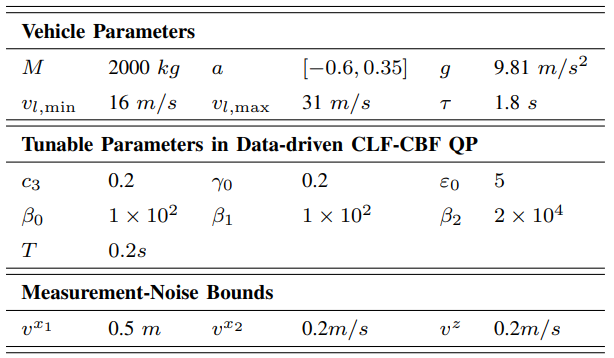

[tau,a,vlm,M,g] = deal(1.8,[-0.6 0.35],16,2000,9.81);
um=0.35;%Passager-comfortable acceleration um M g
[c3,gamma0,epsilon0,beta0,beta1,beta2]=deal(0.2,0.2,5,1e2,1e2,2e4);

Then, we can obtain the corresponding $\mathcal{U}\gets \mathcal P_u, \mathcal{Z}\gets \mathcal P_z$:


$$\mathcal{U} = \{u \mid a_{\min} M g \le u \le a_{\max} M g\},\qquad
\mathcal{Z} = \{r \mid v_{l,\min} \le v_l \le v_{l,\max}\}.
$$


Additionally, we add an upper bound of $$v$$, i.e., $\mathcal{C}\gets \mathcal P_x$:


$$\mathcal{C} = \left\{ x \,\big|\, 
\left[\begin{array}{cc} 1 & -\tau \end{array}\right] x
\ge
0
\right\}.
$$


To accelerate the CIS iterations, we introduce a speed cap and work with the truncated safety set $$\tilde{\mathcal C} = \mathcal C \cap \{ x_2 \le 30 \}$$. Note that the upper limit of speed here is for accelerating convergence, and it is not the final requirement for the safety set.

[Pu,Px,Pz] = deal(Polyhedron([-1;1],[-a(1)*M*g;a(2)*M*g]), Polyhedron(-[1 -tau],-0), Polyhedron([-1;1],[-vlm;vlm+15]));
Pu=Pu.minHRep.minVRep;
Px=Px.minHRep.minVRep;
Pz=Pz.minHRep.minVRep;

PxTilde = Px & Polyhedron([0 1],30);

# ACC Sample

Given that we use the non-linear ACC dynamics, so we just sample $N$ trajectories with $\ell=2(n_u+n_x+n_z+1)$, and sampling time $T$.

ell=2*(nu+nx+nz+1); N=10; T=0.2; nSamples = N*ell;

We sample initial states from a bounded subset of the safety set: $\mathcal{P}_x^{\mathrm{b}} = \mathcal{C} \cap \{x\mid 100 \ge x_1 \ge 0,\ 30 \ge x_2 \ge -10\},$ 

Px_b = Px & Polyhedron([1 0; -1 0; 0 1; 0 -1], [100; 0; 30; -10]);

Meausrement noise

[vkv,vkx]=deal(0.2,0.5);

and auxiliary states from $\mathcal{Z}$. For each trajectory $i=1,\dots,N$, we draw $x_0^{(i)} \in \mathcal{P}_x^{\mathrm{b}},\ z_0^{(i)} \in \mathcal{Z},$ and excite the system in open loop using a random input sequence $\{u_k^{(i)}\}_{k=0}^{\ell-1} \subset \mathcal{U}$. Let $T$ be the sampling time. For each trajectory we simulate the lifted system in Simulink and store the stacked data $
U_0 = \bigl[u_0^{(1)},\dots,u_{\ell-1}^{(N)}\bigr],\quad
X_0 = \bigl[x_0^{(1)},\dots,x_{\ell-1}^{(N)}\bigr],\quad
X_1 = \bigl[x_1^{(1)},\dots,x_{\ell}^{(N)}\bigr],\quad
Z_0 = \bigl[z_0^{(1)},\dots,z_{\ell-1}^{(N)}\bigr].$ 

[U0, X0, X1, Z0] = deal(zeros(nu,nSamples), zeros(nx,nSamples), zeros(nx,nSamples), zeros(nz,nSamples));

for i = 1:N
    colIdx = (i-1)*ell + (1:ell);

    x0=Px_b.randomPoint;
 
    for j=1:ell, U0(:, (i-1)*ell+j)=Pu.randomPoint;end 
    for j=1:ell, Z0(:, (i-1)*ell+j)=Pz.randomPoint;end 

    U0i = timeseries(U0(:,colIdx), (0:ell-1)*T);
    Z0i = timeseries(Z0(:,colIdx), (0:ell-1)*T);

    simOut = sim("ACC_Sample", "SrcWorkspace", "current");

    [X0(:, colIdx),X1(:, colIdx)]=deal(simOut.X(1:end-1, :)',simOut.X(2:end, :)');
end

We keep only those samples whose states lie in $\mathcal{P}_x^{\mathrm{b}}$, i.e., $\bigl(U_0^{\mathrm{full}}, X_0^{\mathrm{full}}, X_1^{\mathrm{full}}, Z_0^{\mathrm{full}}\bigr)
= \bigl(U_0, X_0, X_1, Z_0\bigr)\big| _{\left\{k \, \big|\,  x_k \in \mathcal{P}_x^{\mathrm{b}}\right\}},$

idtemp = find(Px_b.contains(X0)==1); [U0_full, X0_full, X1_full, Z0_full] = deal(U0(:,idtemp), X0(:,idtemp), X1(:,idtemp), Z0(:,idtemp));

## Noise treatment

For numerical smoothing and consistency, we build a scaled regressor matrix

$W
=
\left[
\begin{array}{c}
S_u U_0^{\mathrm{full}}\\[2pt]
S_x X_0^{\mathrm{full}}\\[2pt]
S_z Z_0^{\mathrm{full}}\\[2pt]
\mathbf{1}^\top
\end{array}
\right],
$ where $S_u = \frac{1}{u_m M g},\ S_x = \text{diag}\bigl(1/100,\ 1/30\bigr),\ S_z = \frac{1}{30}.$ 

We then form the least-squares smoothed successor matrix $X_1^{\mathrm{LS}}
=

X_1^{\mathrm{full}} W^\top (W W^\top)^{-1} W,$ and finally select a CIS subset of size $\ell$ by drawing a random index set$\mathcal{I}_{\mathrm{CIS}}\subset\{1,\dots,n_{\text{sample}}\}$ with $|\mathcal{I}^{\mathrm{CIS}}| = \ell$. This gives a denoised, self-consistent data tuple $(U_0, X_0, X_1, Z_0)$ of length $\ell$ used for RCIS construction.

idxCIS = randperm(size(idtemp,2), ell);

W_scale=diag([1/(um*M*g),1/100,1/30,1/30,1]);

W = W_scale * [U0_full; X0_full; Z0_full; ones(1, size(idtemp,2))];

[U0, X0, Z0, X1] = deal(U0_full(:, idxCIS),X0_full(:, idxCIS),Z0_full(:, idxCIS), X1_full* W'/(W*W') * W(:, idxCIS));% 

# Compute Candidate Control Invariant Set

We compute the CIS in the nominal case using a smaller input set in $\mathcal P_u$, and then check whether it can serve as a potential RCIS.

Pu_nom=Polyhedron([-1;1],[um*M*g;um*M*g]);

tic;Xf=AlgorithmCIS(U0,X0,Z0,X1,Pu_nom,PxTilde,Pz);toc; 

Iteration: 12
Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities  14 | Equalities   0
    V-rep (redundant)   : Vertices  13 | Rays   2
Functions : none
历时 8.430771 秒。


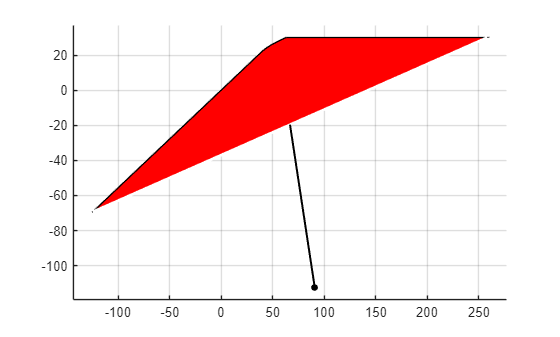

figure;plot(Xf);

# Estimate Uncertainty

We fit $$Q_r=L_r^\top L_r\succeq 0$$, by solving $\min_{Q\succeq 0}\ \text{tr}(Q)
    \ \text{s.t.}
    |e_{j,r}|^2 \le \tilde w_j^\top Q \tilde w_j,
   
    j=1,\dots,M.$ And we get $Q_\mathcal C=L_\mathcal C^\top L_\mathcal C\succeq 0$ by the same way.

A_all = [Xf.A; Px.A];  
    
L_cell = EstimateUncertaintyBoundsFromData(A_all, U0, X0, Z0, X1, U0_full, X0_full, Z0_full,  X1_full, W_scale, 1.2);

历时 1.341737 秒。



[Lx_cell,Lc]= deal(L_cell(1:size(Xf.A, 1)),L_cell{end});

# Verify RCIS

eta=1e2; tic; report = VerifyRCIS(Xf, U0, X0, Z0, X1, Pu, Pz, Lx_cell, W_scale, eta); toc


=== RCIS Verification Report ===
Pgx vertices: 13, Pgz vertices: 2
Total pairs: 26 | Feasible: 26 | Infeasible: 0
RCIS satisfied: true

历时 2.387851 秒。


# ACC Simulation

Initialize the controllers

C=[0 1];

Ctrl={};
Ctrl{1} = ControlAlgorithm2(Xf,Pu,Px,C,U0,X0,Z0,X1,c3,gamma0,epsilon0,beta0,beta1,beta2,Lx_cell,Lc,W_scale,[0 0 0]);
Ctrl{2} = ControlAlgorithm2(Xf,Pu,Px,C,U0,X0,Z0,X1,c3,gamma0,epsilon0,beta0,beta1,beta2,Lx_cell,Lc,W_scale,[1 0 0]);
Ctrl{3} = ControlAlgorithm2(Xf,Pu,Px,C,U0,X0,Z0,X1,c3,gamma0,epsilon0,beta0,beta1,beta2,Lx_cell,Lc,W_scale,[1 1 0]);
Ctrl{4} = ControlAlgorithm2(Xf,Pu,Px,C,U0,X0,Z0,X1,c3,gamma0,epsilon0,beta0,beta1,beta2,Lx_cell,Lc,W_scale,[1 1 1]);

mdl='ACC_sim'; 

baseSim = Simulink.SimulationInput(mdl);

Adopt the quadratic Lyapunov function $\(V(x) = (Cx-r)^\top (Cx-r)\) with \(P = C^\top C \succeq 0\)$.

baseSim = baseSim.setVariable('T',      T) ...
                 .setVariable('nx',     nx) ...
                 .setVariable('nu',     nu) ...
                 .setVariable('nz',     nz) ...
                 .setVariable('x0',    [81;17]) ...
                 .setVariable('vkv',   vkv) ...
                 .setVariable('vkx',   vkx) ...
                 .setVariable('rk',    30);

simIn(1:4,1) = baseSim; 
simIn(1) = simIn(1).setVariable('CaseId', 1);
simIn(2) = simIn(2).setVariable('CaseId', 2);
simIn(3) = simIn(3).setVariable('CaseId', 3);
simIn(4) = simIn(4).setVariable('CaseId', 4);

tic 
    simOut = parsim(simIn,'ShowProgress','on','UseFastRestart','off','TransferBaseWorkspaceVariables','on');

[16-Dec-2025 17:14:57] 正在检查并行池的可用性...
[16-Dec-2025 17:14:57] 正在并行工作进程上启动 Simulink...
[16-Dec-2025 17:14:58] 正在并行编译模型引用...
[16-Dec-2025 17:14:58] 正在并行工作进程上配置仿真缓存文件夹...
[16-Dec-2025 17:14:58] 正在将模型中使用的基础工作区变量传输给并行工作进程...
[16-Dec-2025 17:14:58] 要发送到并行工作进程的基础工作区变量的总大小为 2.87 MB。
[16-Dec-2025 17:14:58] 正在并行工作进程上加载模型...
[16-Dec-2025 17:15:04] 正在运行仿真...
[16-Dec-2025 17:15:24] 已完成 1 次仿真运行，共 4 次
[16-Dec-2025 17:15:24] 从并行工作进程接收的运行 1 的仿真输出(大小: 39.65 KB)。
[16-Dec-2025 17:15:24] 已完成 2 次仿真运行，共 4 次
[16-Dec-2025 17:15:24] 从并行工作进程接收的运行 2 的仿真输出(大小: 39.65 KB)。
[16-Dec-2025 17:15:25] 已完成 3 次仿真运行，共 4 次
[16-Dec-2025 17:15:25] 从并行工作进程接收的运行 3 的仿真输出(大小: 39.65 KB)。
[16-Dec-2025 17:15:25] 已完成 4 次仿真运行，共 4 次
[16-Dec-2025 17:15:25] 从并行工作进程接收的运行 4 的仿真输出(大小: 87.31 KB)。
[16-Dec-2025 17:15:25] 正在清理并行工作进程...


toc 

历时 29.947514 秒。


load('EnvirInfo.mat');display(report);

report =     'Environment (reproducibility).
       OS: Windows Microsoft Windows 11 专业版
       CPU: 12th Gen Intel(R) Core(TM) i7-12700KF (12 cores)
       MATLAB: MATLAB 25.1.0.2973910 (R2025a) Update 1 (R2025a, Update 1)
       Solvers/Libraries: MOSEK: MOSEK Version 11.0.14 (Build date: 2025-4-3 22:32:03); YALMIP: 20250626; MPT3: 3.2.1
       MATLAB toolboxes (required by LK_demo + LK_sim): Control System Toolbox, Simulink
       MATLAB toolboxes (required by ACC_demo + ACC_Sample + ACC_sim): Automated Driving Toolbox, Simulink
     '


# Visualisation

    Case    Nsteps    Mean_ms    Median_ms    P95_ms
    ____    ______    _______    _________    ______

     1       500      8.0936      7.3746       13.94
     2       500      8.0981      7.2176      14.148
     3       500      10.007      8.8814      16.564
     4       500      9.8716       9.143      14.968

Overall pooled: mean NaN ms, median NaN ms, p95 NaN ms

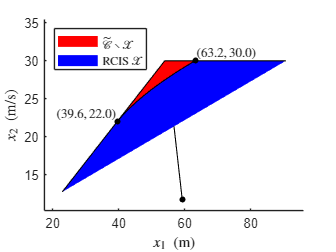

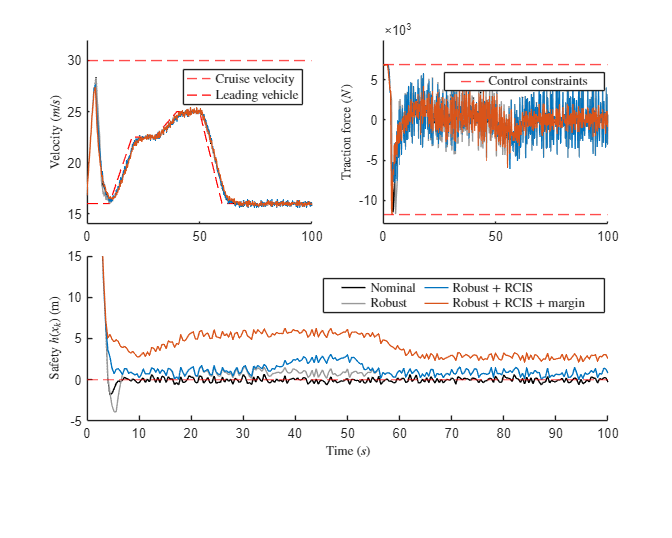

run('ACC_draw.mlx');